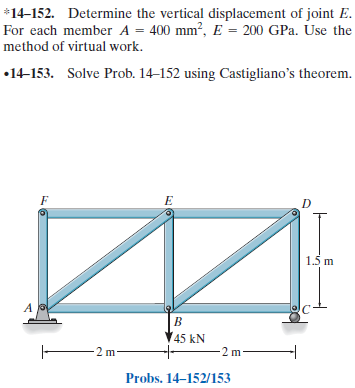

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-152RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-152RP-solution-9780136022305) (problem 14-152)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-153RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-153RP-solution-9780136022305) (problem 14-153)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

jointA = [0 0]*u.m;
jointB = [2 0]*u.m;
jointC = [4 0]*u.m;
jointD = [4 1.5]*u.m;
jointE = [2 1.5]*u.m;
jointF = [0 1.5]*u.m;

# member data

E = 200*u.GPa;
A = 400*u.mm^2;

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rc', {0 'Rcy'}, jointC);
t = t.add('concentrated', 'Pb', [0 -45]*u.kN, jointB);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('joint', 'F', jointF);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fae', jointA, jointE, E, A);
t = t.add('member', 'Faf', jointA, jointF, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fbd', jointB, jointD, E, A);
t = t.add('member', 'Fbe', jointB, jointE, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);
t = t.add('member', 'Fde', jointD, jointE, E, A);
t = t.add('member', 'Fef', jointE, jointF, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 3) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & 0.75\,\mathrm{mm}\\ \mathrm{vB} & -3.38\,\mathrm{mm}\\ \mathrm{uC} & 0.75\,\mathrm{mm}\\ \mathrm{vC} & 0\\ \mathrm{uD} & 0\\ \mathrm{vD} & -0.422\,\mathrm{mm}\\ \mathrm{uE} & 0.75\,\mathrm{mm}\\ \mathrm{vE} & -2.95\,\mathrm{mm}\\ \mathrm{uF} & 0.75\,\mathrm{mm}\\ \mathrm{vF} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m) %#ok<NASGU>

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 30.0\,\mathrm{kN}\\ \mathrm{Fae} & -37.5\,\mathrm{kN}\\ \mathrm{Faf} & 0\\ \mathrm{Fbc} & 0\\ \mathrm{Fbd} & 37.5\,\mathrm{kN}\\ \mathrm{Fbe} & 22.5\,\mathrm{kN}\\ \mathrm{Fcd} & -22.5\,\mathrm{kN}\\ \mathrm{Fde} & -30.0\,\mathrm{kN}\\ \mathrm{Fef} & 0 \end{array}\right)$$

la_f_c_vpa = vpa(la.f.c) %#ok<NASGU> 

$$la\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 22.5\,\mathrm{kN} & 0\\ \mathrm{Rc} & 0 & 22.5\,\mathrm{kN} & 0\\ \mathrm{Pb} & 0 & -45.0\,\mathrm{kN} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 30.0\,\mathrm{kN} & 0 & 0\\ \mathrm{Fae} & -30.0\,\mathrm{kN} & -22.5\,\mathrm{kN} & 0\\ \mathrm{Faf} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fbd} & 30.0\,\mathrm{kN} & 22.5\,\mathrm{kN} & 0\\ \mathrm{Fbe} & 0 & 22.5\,\mathrm{kN} & 0\\ \mathrm{Fcd} & 0 & -22.5\,\mathrm{kN} & 0\\ \mathrm{Fde} & 30.0\,\mathrm{kN} & 0 & 0\\ \mathrm{Fef} & 0 & 0 & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m, 3) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 22.5\,\mathrm{kN}\\ \mathrm{Rc} & 22.5\,\mathrm{kN}\\ \mathrm{Pb} & 45.0\,\mathrm{kN} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fae} & 0\\ \mathrm{Faf} & 0\\ \mathrm{Fbc} & 0\\ \mathrm{Fbd} & 45\,\mathrm{kN}\,m\\ \mathrm{Fbe} & 45\,\mathrm{kN}\,m\\ \mathrm{Fcd} & 90\,\mathrm{kN}\,m\\ \mathrm{Fde} & 45\,\mathrm{kN}\,m\\ \mathrm{Fef} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rc} & 0 & 0 & 90\,\mathrm{kN}\,m\\ \mathrm{Pb} & 0 & 0 & -90\,\mathrm{kN}\,m \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fae} & 0 & 0 & 0\\ \mathrm{Faf} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fbd} & 0 & 0 & 45\,\mathrm{kN}\,m\\ \mathrm{Fbe} & 0 & 0 & 45\,\mathrm{kN}\,m\\ \mathrm{Fcd} & 0 & 0 & -90\,\mathrm{kN}\,m\\ \mathrm{Fde} & 0 & 0 & -45\,\mathrm{kN}\,m\\ \mathrm{Fef} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rc} & 90\,\mathrm{kN}\,m\\ \mathrm{Pb} & 90\,\mathrm{kN}\,m \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa ma_f_c_vpa la_f_c_vpa la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;